## Семинар 20. Объектно-ориентированное программирование

**ООП** - это один из способов организации как самого кода, так и логики его работы  и написания (парадигма). Наиболее распространенные парадигмы программирования:

- Функциональное (Haskell)

- Процедурно-ориентированное (Fortran,Pascal,C,Basic)

- Объектно-ориентированное (Java, C++, Python)

*языки программирования написаны тут условно, так как логика программирования может быть реализована в любом из языков в той или иной степени.

Чистое **функциональное программирование** - все должно быть набором чистых функций, которые не имеют побочных действий, не изменяют "состояний", а только  выходные аргументы,  входные аргументы - не изменяемы, в идеале функции программы ведут себя как математические функции - осуществляют мэппинг из множеств входных аргументов на множества выходных.

Основной идеей **процедурного программирования **является то, что все должно быть сделано последовательным набором шагов (шагами может быть и вызов функций)

**Объектно-ориентированное** программирование рассматривает программу как набор объектов, взаимодействующих друг с другом по определенным правилам (передающим друг другу сообщения), причем, как правило, под объектом подразумевается конструкция как объединяющая в себе  данные, так  и декларирующая действия которые можно с ними производить - "язык" обращения к объекту извне  - со стороны другого объекта.

**matlab** - это мультипарадигмальный язык (как многие прочией современные языки, использующиеся в научном прогаммировании: **python**, **julia**)

Примеры - программы для расчета суммы элементов массива.

clearvars
a = rand(10);
sum(a,'all')

ans = 52.1469

procedural_example(a) % proc

ans = 52.1469

functional_example(a) % func (recursion)

ans = 52.1469

iterator_example(a) % special object - iterator

ans = 52.1469

#### Терминология

ООП объединяет данные и действия в одну конструкцию которая называется `объект`. В ООП большой проект рассматривается как взаимодействие объектов друг другом через **интерфейсы**, которые четко прописаны в спецификации объектов. Сам объект, внутри себя может жить своей жизнью. ООП позволяет проще организовать одновременную работу над кодом нескольких программистов, упрощает поддержку кода, упрощает создание API и документации, так как весь код структурирован.

Недостатки - требует большей квалификации от программиста, так как требуется продумывать структуру программы до ее написания. Трудности при конкурентном выполнении из-за возможности "data race" которые возникает когда сообщения от двух объектов пытаются изменить состояние третьего объекта одновременно. Б**о**льший объем кода.

**Класс** - это заготовка  для создания объектов. Матлаб особо не разделяет понятие типа и понятие классса, можно сказать, что в матлаб, класс  - это пользовательский тип.

Конструкции в памяти компьютера, созданные по этим заготовкам - это **экземпляры** класса (**instance**). Экземпляры называют **объектами**, я не вижу разницы между объектом класса  и экземпляром класса (также эту разницу не видят создатели документации матлаб)

clearvars
a = 10;
b = 'fghj';
c = figure();
d = struct("a",1,"b",2);
e = {1,2,"f"};
c2= figure(c);
c3 = figure();
isequal(c,c2)

ans = logical
   1


isequal(c3,c2)

ans = logical
   0


f1 = handle(9)


f1 =

	handle



whos

  Name      Size            Bytes  Class               Attributes

  a         1x1                 8  double                        
  ans       1x1                 1  logical                       
  b         1x4                 8  char                          
  c         1x1                 8  matlab.ui.Figure              
  c2        1x1                 8  matlab.ui.Figure              
  c3        1x1                 8  matlab.ui.Figure              
  d         1x1               352  struct                        
  e         1x3               494  cell                          
  f1        1x1                    handle                        



#### Основные постулаты ООП

1. **Encapsulation**:

Инкапсуляция это, во-первых сама идея объединения кода и данных в одно целое - объек, во-торых  - это возможность ограничивать использование внутренних функций и свойств объекта  "извне". Программист обозначает в коде те функции, которые доступны в качестве интерфейса взаимодействия с объектом. А также те свойства объекта, которые могут изменяться другими объектами.

**2. ****Modularity (модульность)**

Позволяет разделить программу на логически изолированные блоки, каждый из которых достаточно прост и понятен по отдельности ( в теории)  

**3. ****Abstraction (абстрация)**

Абстрация позволяет писать "неработающий" код, который затем оживляется при реализации абстрации. То есть, на определенном этапе написания программы мы можем оставлять некоторые (или все) функции класса нереализованными, создавая таким образом абстратные классы.  Это позволяет продумать логику работы программы не вдаваясь в детали реализации, так, как будто функции, выполняющие некоторые операции уже существуют. Реализацию абстракций мы оставляем на потомков абстрактного класса. Ключевой особенностью абстрактного класса является то, что не может существовать объекта абстрактного класса.

4. **Inheritance (наследование)**:

Позволяет строить иерархию классов, когда класс - потомок наследует методы и свойства своего класса предка  (суперкласса). Существуют разные модели наследования, но в матлаб, объект потомка суперкласса является также и объектом самого суперкласса. Таким образом, объект может быть объектом более чем одного числа классов. 

Запись: Квадрат <: Геометрическая фигура обозначает, что класс "Квадрат" наследует суперклассу "Геометрическая фигура".

5. **Polymorphism (полиморфизм)**

Грубо говоря, полиморфизм обозначает, что метод с одним и тем же названием может делать разные вещи в зависимости от того к какому классу он относится. Метод класса потомка может переопределить часть методов класса предка, а остальные оставить как есть.

#### Основные термины:

- **Class** definition — код класса.

- **Properties** — данные

- **Methods** — специальная форма функций, которые вызываются на объекте класса

- **Events** — специальные сообщения, которые позволяют объекту оповещать другие объекты о своем состоянии

- **Attributes** — аттрибуты позволяют определять поведение свойств и методов класса

- **Listeners** — слушатели - это объекты, которые слушают Events

- **Objects** — эземпляры класса

- **Subclass** — класс - потомок,  наследует методы, свойства и ивенты класса - предка

- **Superclass** — класс-предок

#### Когда нужно ООП?

Когда программу можно представить в виде дерева 

#### Общая структура класса

Создаем два экземпляра одного класса

o1 = OneD(6)

o1 =   OneD with properties:

    x: 6


o2 = OneD(7)

o2 =   OneD with properties:

    x: 7


o1.x

ans = 6

o1.x=15

o1 =   OneD with properties:

    x: 15


o3 = o1 +  o2 % a + b <=> plus(a,b)

o3 =   OneD with properties:

    x: 22


ans = 3

o3 =   OneD with properties:

    x: 22


plus(1,1)

ans = 2

plus(o1,o2)

ans =   OneD with properties:

    x: 22


o_array = OneD.empty(10,0)


o_array = 

  10×0 OneD array with properties:

    x



isempty(o_array)

ans = logical
   1


isa(o_array,"OneD")

ans = logical
   1


numel(o_array)

ans = 0

Создание массива при помощи setindex

clearvars x
x(10) = 15

x =      0     0     0     0     0     0     0     0     0    15



ans =

     []



OneD()

ans =   OneD with properties:

    x: 0


Попробуем создать массив объектов нашего класса

o_array1(10) = OneD(9) 
o_array1(8)

ans =   OneD with properties:

    x: 0


o_array2 = arrayfun(@OneD,1:10) % в явном виде вызываем конструктор

sum(o_array2)

ans =   OneD with properties:

    x: 55


sum(1:10)

ans = 55

#### Наследование

t1 = TwoD(10,9)

t1 =   TwoD with properties:

    y: 9
    x: 10


t2 = TwoD(20,5)

t2 =   TwoD with properties:

    y: 5
    x: 20


t1 + t2

ans =   TwoD with properties:

    y: 14
    x: 30


t1.plus(t2)

ans =   TwoD with properties:

    y: 14
    x: 30


plus(o1,OneD(6)) %OneD(6)

ans =   OneD with properties:

    x: 12


struct("x",10,"y",15) + struct("x",10,"y",15)

Operator '+' is not supported for operands of type 'struct'.

t_array = [t1,t2]

sum(t_array) % вызываем метод наслудованный от суперкласса

ans =   TwoD with properties:

    y: 14
    x: 30


#### value vs handle классы 

#### pass-by-value vs pass-by-reference

clearvars
% структуры передаются по содержимому
fun = @(o) eval("o.x=100;whos;disp(o);"); % создаем анонимную функцию которая присваивает новое значение полю x своего аргумента
A = struct("x",0,"b",10)

A = struct with fields:
    x: 0
    b: 10


A.x

ans = 0

fun(A)

  Name      Size            Bytes  Class     Attributes

  o         1x1               352  struct              

    x: 100
    b: 10



A.x

ans = 0

%массивы тоже передаюстя по содержимому
fun_indexing = @(o) eval("o(5)=100;whos;disp(o);");
A = [1,2,3,4,5,6]

A =      1     2     3     4     5     6


fun_indexing(A)

  Name      Size            Bytes  Class     Attributes

  o         1x6                48  double              

     1     2     3     4   100     6



A

A =      1     2     3     4     5     6


clear all
f = figure(10)

f =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


f.Name


ans =

  0×0 empty char array



fun_rename = @(o) eval("o.Name=string(333);");
fun_rename(f)
f.Name

ans = '333'

delete(f)

fun = @(o) eval("o.x=100;whos;disp(o);");
o1 = OneD(6)

o1 =   OneD with properties:

    x: 6


o1.x

ans = 6

fun(o1)

  Name      Size            Bytes  Class    Attributes

  o         1x1                 8  OneD               

  OneD with properties:

    x: 100



o1.x

ans = 6

o1h = OneDhandle(6)

o1h =   OneDhandle with properties:

    x: 6


o1h.x

ans = 6

fun(o1h)

  Name      Size            Bytes  Class         Attributes

  o         1x1                 8  OneDhandle              

  OneDhandle with properties:

    x: 100



o1h.x

ans = 100

Разница между передачей аргумента по указателю и по содержимому

fun_modify(o1) % объект value - класса передается по содержимому

Unrecognized function or variable 'fun_modify'.

fun_modify(o1h) % обект потомок handle класса передается по указателю

#### Абстрактные классы

Помогают выстроить структуру кода если она укладывается в стурктуру типа дерева.

Абстракции популярны в математике, например возьмем векторное пространство.

VectorSpace() % наличие абстрактного метода или свойства делает класс абстрактным

Abstract classes cannot be instantiated. Class 'VectorSpace' defines abstract methods and/or properties.

v1 = NumVectors([1 2 3])

v1 = Вектор с координатами 1, 2, 3

v2 = NumVectors([1 0 0])

v2 = Вектор с координатами 1, 0, 0

v3 = NumVectors([1 0 1])

v3 = Вектор с координатами 1, 0, 1

sum(v1,v2,v3)

ans = Вектор с координатами 3, 2, 4

c1 = CircVectorSpace(5)

c1 = Круг с радиусом 5 площадью 78.5398

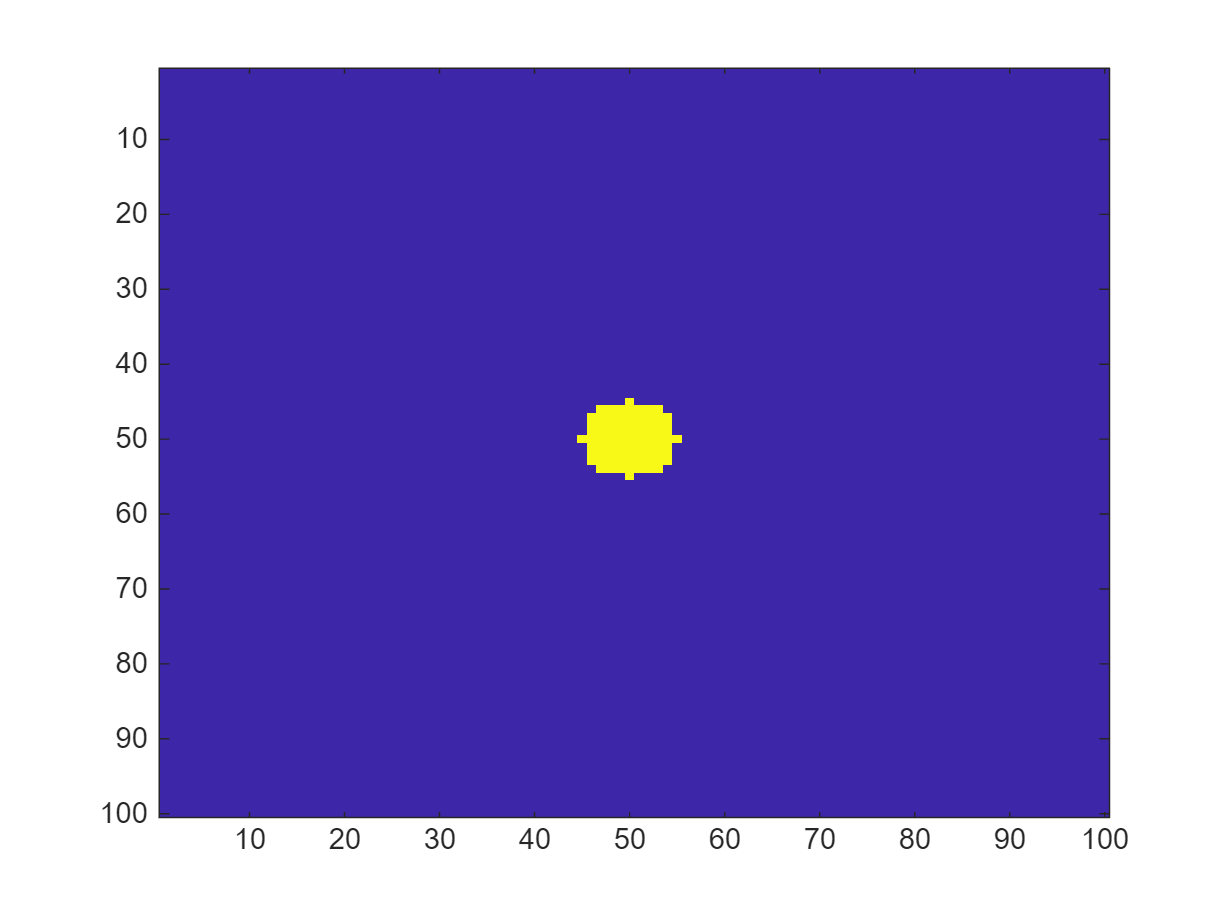

image(show(c1))

c2 = CircVectorSpace(11);
c1 + c2

ans = Круг с радиусом 12 площадью 452.3893

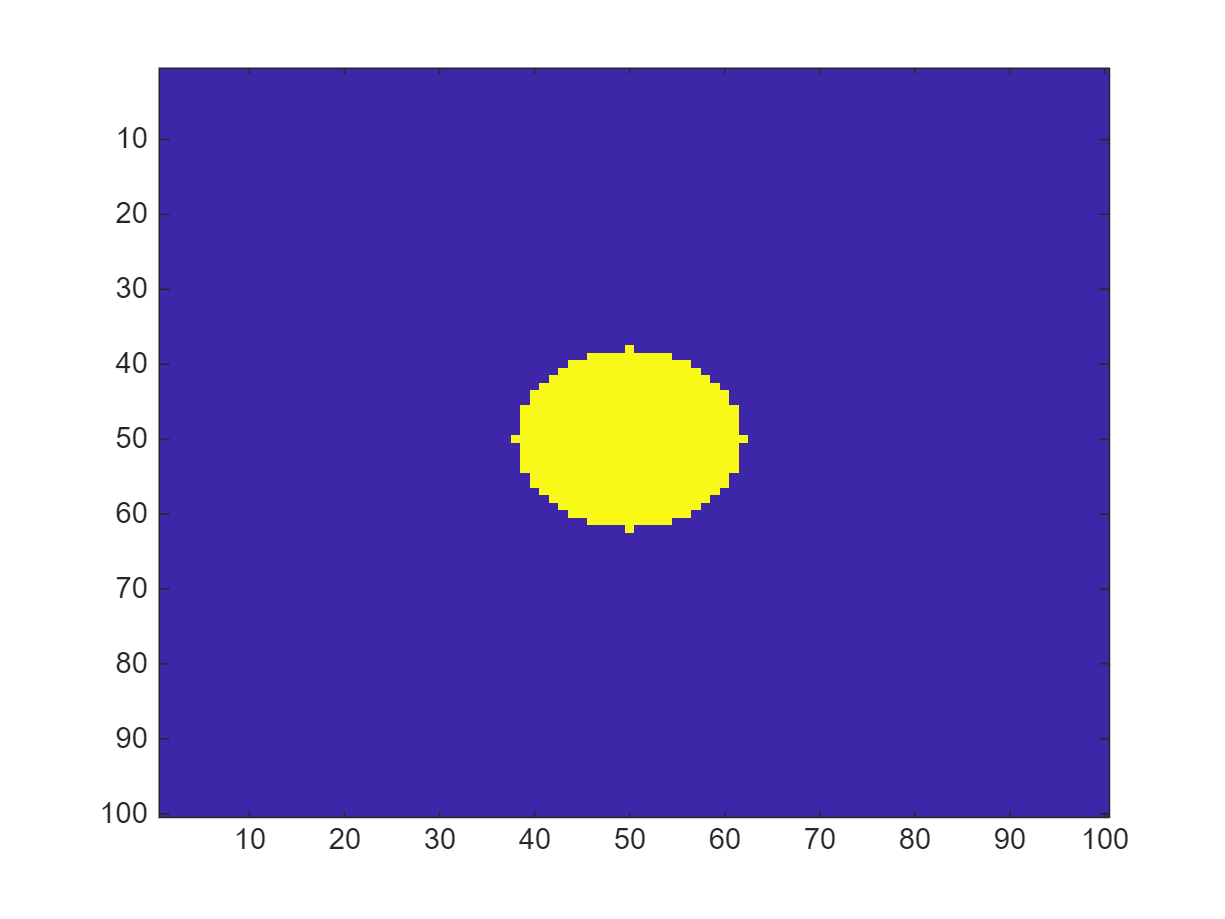

image(show(c1 + c2))

Удобно использовать абстрактные классы как признак объекта

По сути это флажок, который гарантирует, что объекты потомков этого класса будут иметь метод run

#### Множественное наследование

В матлабе есть множественное наследование, то есть, класс может наследовать одновременно от нескольких суперклассов.

(что будет если оба суперкласса реализуют методы с одинаковым названием?)

Обычно это зло, исключение составляют интерфейсы (абстрактные классы декларирующие необходимость реализовать метод или группу методов), а также ситуации, когда структура абстракций четко прослеживается 

#### Матлаб и multiple dispatch

Как матлаб определяет какую функцию вызвать?

Для эксперимента добавим к описанным выше классам методы triplus, которые позволяют суммировать три объекта имеющих поля "x"

o1 = OneD(1);
o2 = OneDhandle(2);
o3 = struct("x",3);
class(triplus(o1,o2,o3))

OneD method called


ans = 'OneD'

class(triplus(o2,o1,o3))

OneDhandle method called


ans = 'OneDhandle'

class(triplus(o3,o2,o1))

OneDhandle method called


ans = 'struct'

class(triplus(o3,o1,o2))

OneD method called


ans = 'OneD'

triplus(1,o2,o1)

OneDhandle method called


Dot indexing is not supported for variables of this type.

Error in OneDhandle/triplus (line 19)
            o1.x = o1.x + o2.x + o3.x;

Таким образом, какой вызвать метод матлаб определяет по первому среди аргументов, имеющему данный метод. Так, например, третий четвертый вызов вызывают метод второго аргумента, так как первый аргумент имеет тип struct, для которго метод **plus**. Но, почему-то это не работает на последнем вызове...